# Evalution of WIFI6 and WIFI5 Performance Under Single-User format

### Introduction

Over the past few decades, the evolution of wireless communication has led to continuous upgrades in Wi-Fi standards to support growing demands for QoS. While Wi-Fi 6 (802.11ax) is widely recognized for enhancing performance in multi-user environments through technologies like OFDMA and MU-MIMO, it's also important for us to understand how it performs in single-user conditions compared with previous standards. This project will focus on comparing the performance of 802.11ax and 802.11ac under single-user format.

## Approach and Design

To evaluate the performance of 802.11ax and 802.11ac, we mainly use throughput as the metric. There are two simulation programs, AX_SUsimulation and AC_SUsimulation that simulate the end to end system of 802.11ax and 802.11ac respectively. For both of them, we generate random bits based on their psdu length of current configuration and then passing the wave generated by those bits through the TGAX or TGAC channel accordingly, applying path loss and adding noise. At the receiver side of 802.11ac, frequency offset correction is applied before data recovery, and we use the received data, channel estimation, and noise estimation to recover the transmitted bits, which are then compared with the original bits to calculate throughput. While for 802.11ax, we use the equalized symbols and channel state information, along with noise estimation, to recover the bits for throughput evaluation.

## Part1 : The Effect of SNR

In this section, we are going to investigate how the signal-to-noise ratio (SNR) influences the throughput performance of Wi-Fi 6 (802.11ax) and Wi-Fi 5 (802.11ac) under single-user conditions. 

### Observations:  

For **low snr (0db to 10db)**, both 802.11ax and 802.11ac have zero throughput . 

For **mid snr (15db to 25db)**, the throughput of 802.11ac ramps much faster compared to 802.11ax.

For **high snr(25db to 50db)**, 802.11ax surpasses 802.11ac, reaching a maximum throughput slightly above 50 Mbps, while 802.11ac plateaus at 45 Mbps.

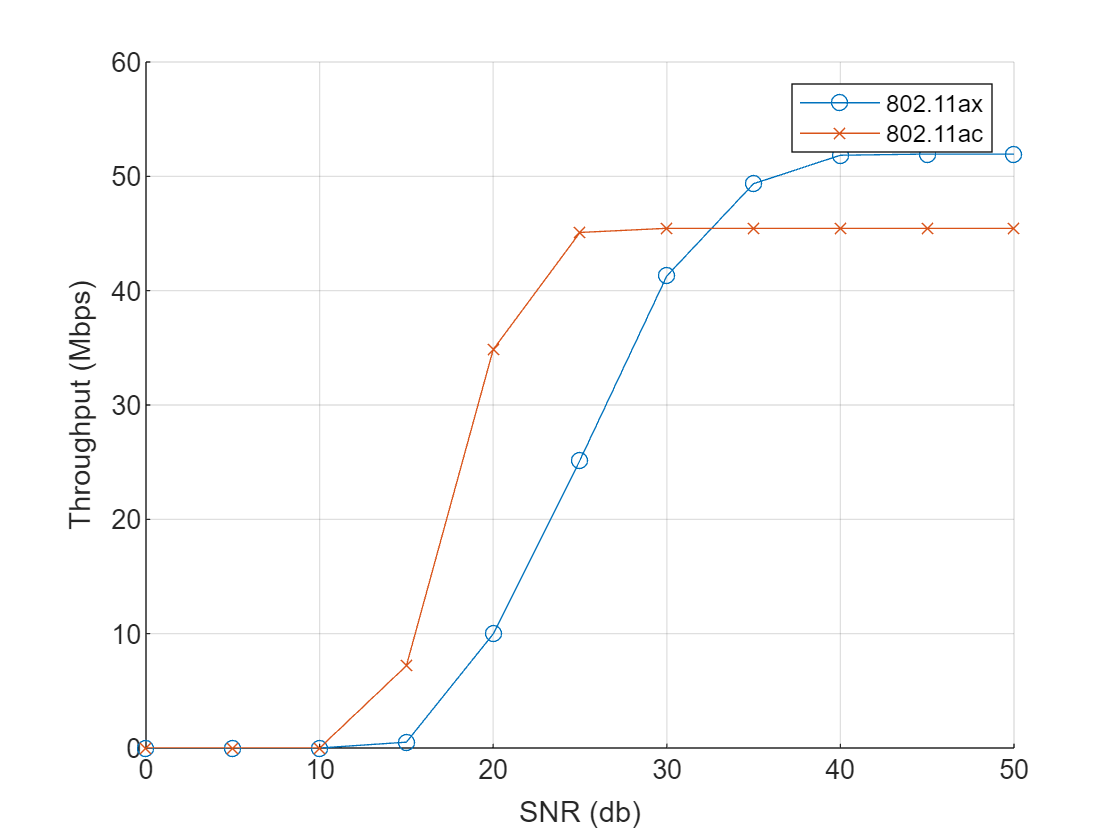

Nsimulation = 500;
snr = 0:5:50;
Nsnr = numel(snr);

%setup high-efficiency single user waveform
cfgHE = su_setup("HE", 'CBW20', 'Direct', 2, 2, 2000, 0.8, 3);

%setup VHT 
cfgVHT = su_setup("VHT", 'CBW20', 'Direct', 2, 2, 2000, 'Long', 3);

%setup TGAX channel
TGAXchannel = channel_setup("TGAX", 'CBW20', wlanSampleRate(cfgHE), 'Model-C', 2, 2, 0.089);

%setup TGAC channel
TGACchannel = channel_setup("TGAC", 'CBW20', wlanSampleRate(cfgVHT), 'Model-C', 2, 2, 0.089);

%run simulation
throughput_AX = AX_SUsimulation(cfgHE, TGAXchannel, snr, Nsimulation, 0);
throughput_AC = AC_SUsimulation(cfgVHT, TGACchannel, snr, Nsimulation, 0);

figure()
hold on;
plot(snr, throughput_AX.', '-o', 'DisplayName', '802.11ax');
plot(snr, throughput_AC.', '-x', 'DisplayName', '802.11ac');
legend('show')
xlabel('SNR (db)');
ylabel('Throughput (Mbps)');
grid on;
hold off;

## Part2: The Effect of Delay profile

This part examines the impact of different delay profiles, which represent varying multipath propagation environments. Using standardized channel models (Model-A for **Flat fading**, Model-C for **Indoor residential or small office**, and Model-F for **Large space indoor**)

### Observations:  

For the three delay models, the trends of throughput are similar comparing to part1 and their highest throughputs are roughly the same. But under model-F, both 802.11ax and 802.11ac reach their highest throughput with relatively lower SNR compared to model-A and model-C.

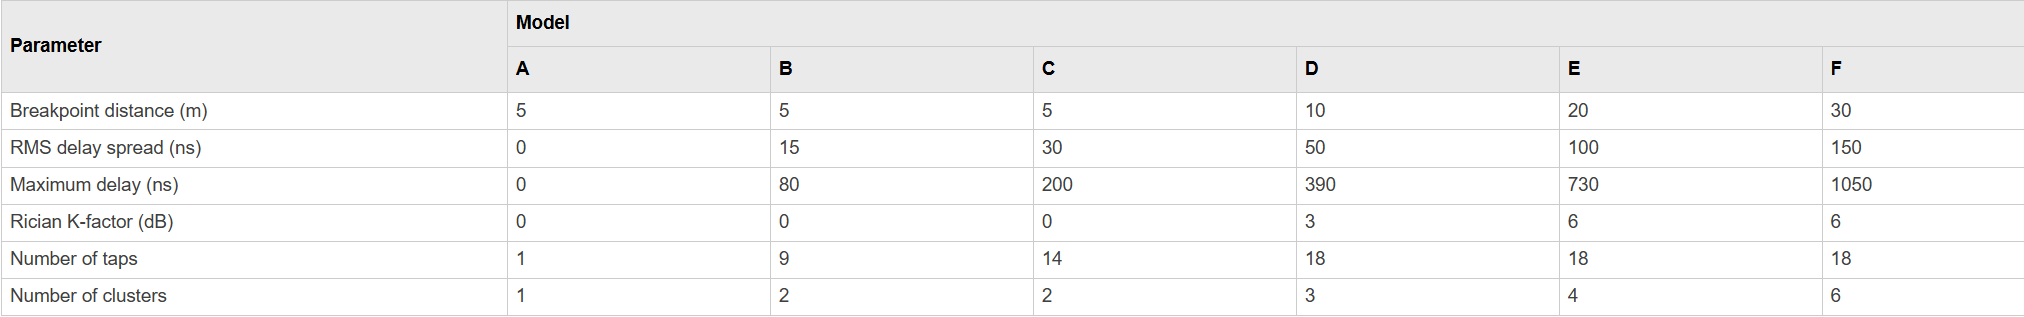

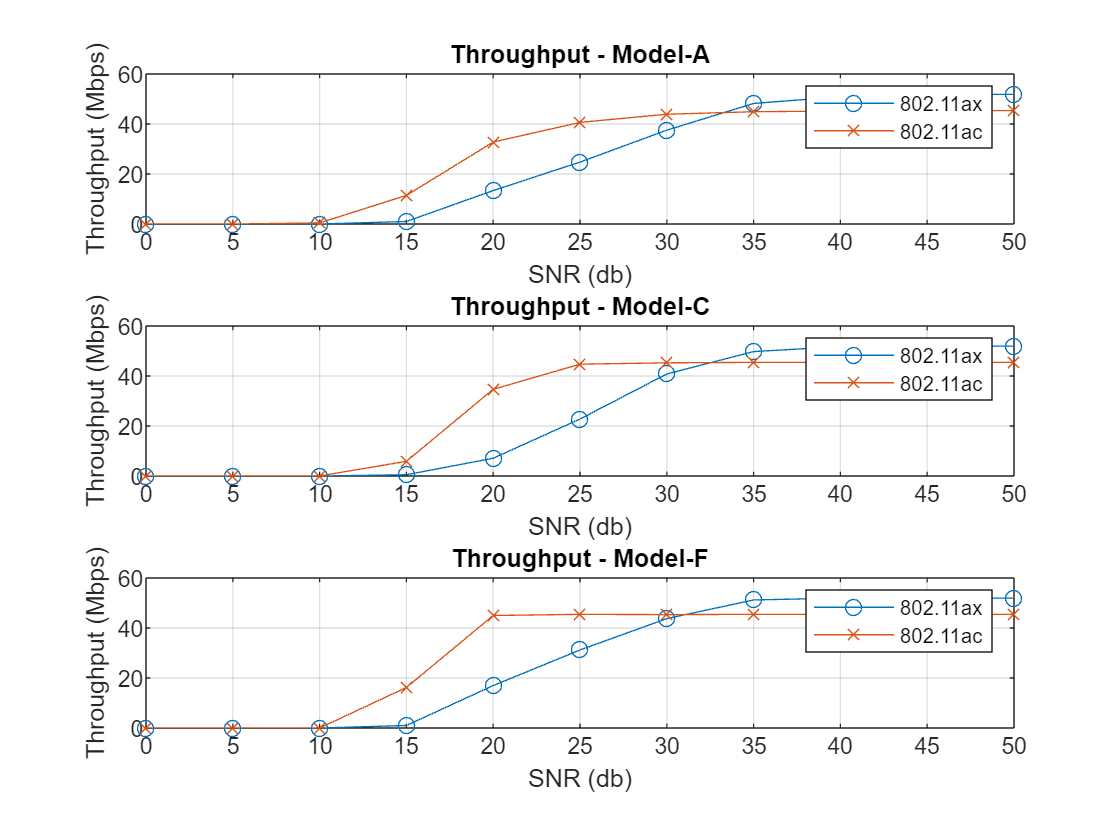

models = {'Model-A', 'Model-C', 'Model-F'};
Nmodels = numel(models);
throughputResults_AX = zeros(Nmodels, Nsnr);
throughputResults_AC = zeros(Nmodels, Nsnr);

%simulating different delay profiles
for i = 1 : Nmodels
    model = models{i};

    TGAXchannel = channel_setup("TGAX", 'CBW20', wlanSampleRate(cfgHE), model, 2, 2, 0.089);
    throughputResults_AX(i, :) = AX_SUsimulation(cfgHE, TGAXchannel, snr, Nsimulation, 0);

    TGACchannel = channel_setup("TGAC", 'CBW20', wlanSampleRate(cfgVHT), model, 2, 2, 0.089);
    throughputResults_AC(i, :) = AC_SUsimulation(cfgVHT, TGACchannel, snr, Nsimulation, 0);

end

figure;
for i = 1:Nmodels
    subplot(Nmodels,1,i);
    plot(snr, throughputResults_AX(i,:), '-o', snr, throughputResults_AC(i,:), '-x');
    xlabel('SNR (db)');
    ylabel('Throughput (Mbps)');
    title(['Throughput - ' models{i}]);
    legend('802.11ax', '802.11ac');
    grid on;
end

## Part3: The Effect of Modulation Method

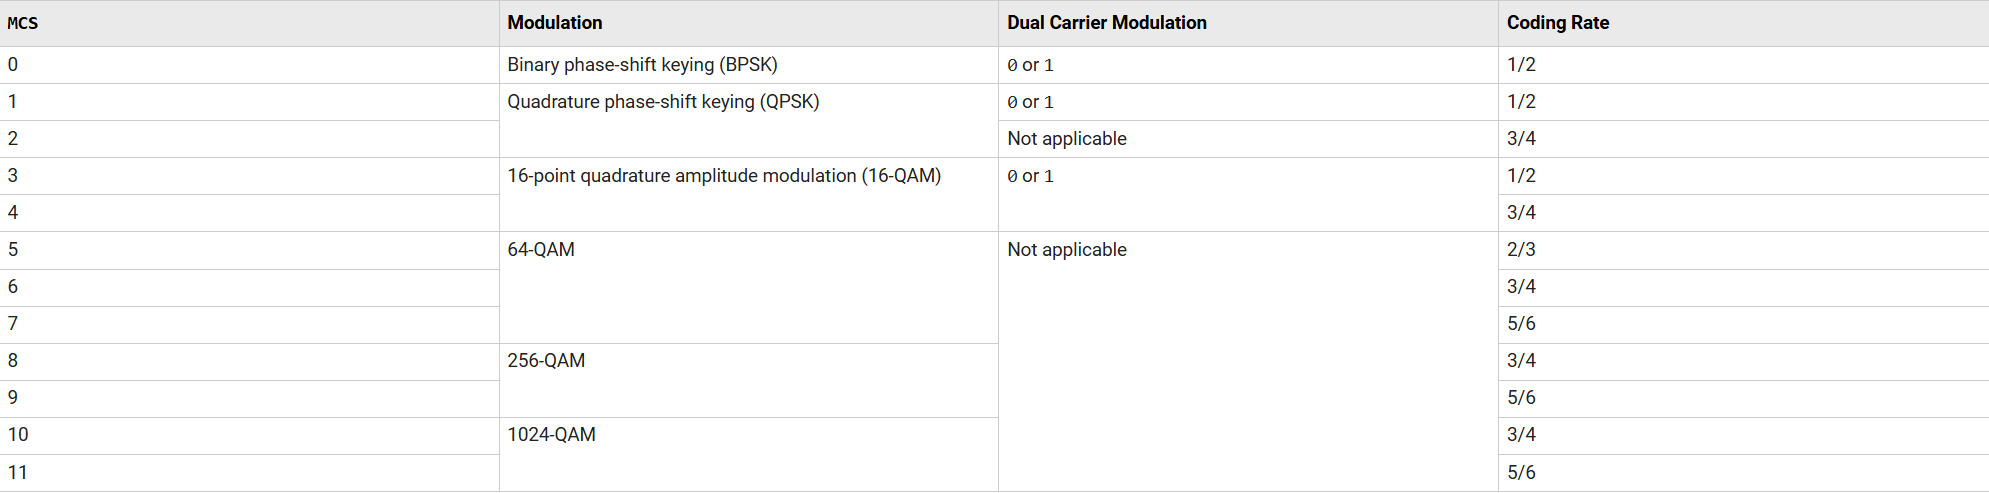

In this section, we are going to analyze how different MCSs can affect the throughput performance of 802.11ax and 802.11ac under varying SNR conditions.

**Observations:  **

As the modulation increases, higher throughputs are achieved for both 802.11ax and 802.11ac, while the requirement of SNR also increases, since higher-order modulation schemes are more sensitive to noise and require better signal quality to maintain reliable communication.

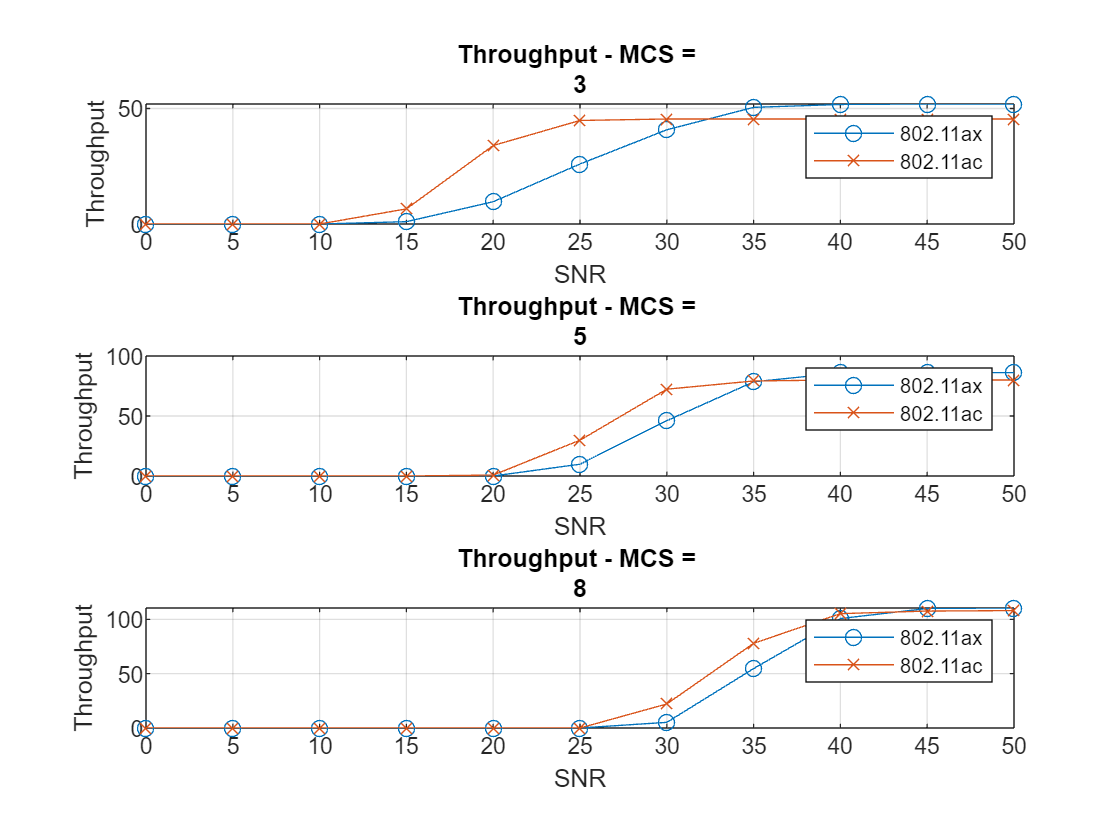

MCS  = {3, 5, 8};
Nmcs = numel(MCS);
throughputResults_AX = zeros(Nmcs, Nsnr);
throughputResults_AC = zeros(Nmcs, Nsnr);

%simulating different modulation schemes
for i = 1 : Nmcs
    modulation = MCS{i};

    %setup high-efficiency single user waveform
    cfgHE = su_setup("HE", 'CBW20', 'Direct', 2, 2, 2000, 0.8, modulation);

    %setup VHT 
    cfgVHT = su_setup("VHT", 'CBW20', 'Direct', 2, 2, 2000, 'Long', modulation);

    TGAXchannel = channel_setup("TGAX", 'CBW20', wlanSampleRate(cfgHE), 'Model-C', 2, 2, 0.089);
    TGACchannel = channel_setup("TGAC", 'CBW20', wlanSampleRate(cfgVHT), 'Model-C', 2, 2, 0.089);

    throughputResults_AX(i, :) = AX_SUsimulation(cfgHE, TGAXchannel, snr, Nsimulation, 0);

    throughputResults_AC(i, :) = AC_SUsimulation(cfgVHT, TGACchannel, snr, Nsimulation, 0);

end

figure;
for i = 1:Nmcs
    subplot(Nmcs, 1, i)
    plot(snr, throughputResults_AX(i,:), '-o', snr, throughputResults_AC(i,:), '-x');
    xlabel('SNR');
    ylabel('Throughput');
    title(['Throughput - MCS = ' MCS(i)])
    legend('802.11ax', '802.11ac');
    grid on;
end

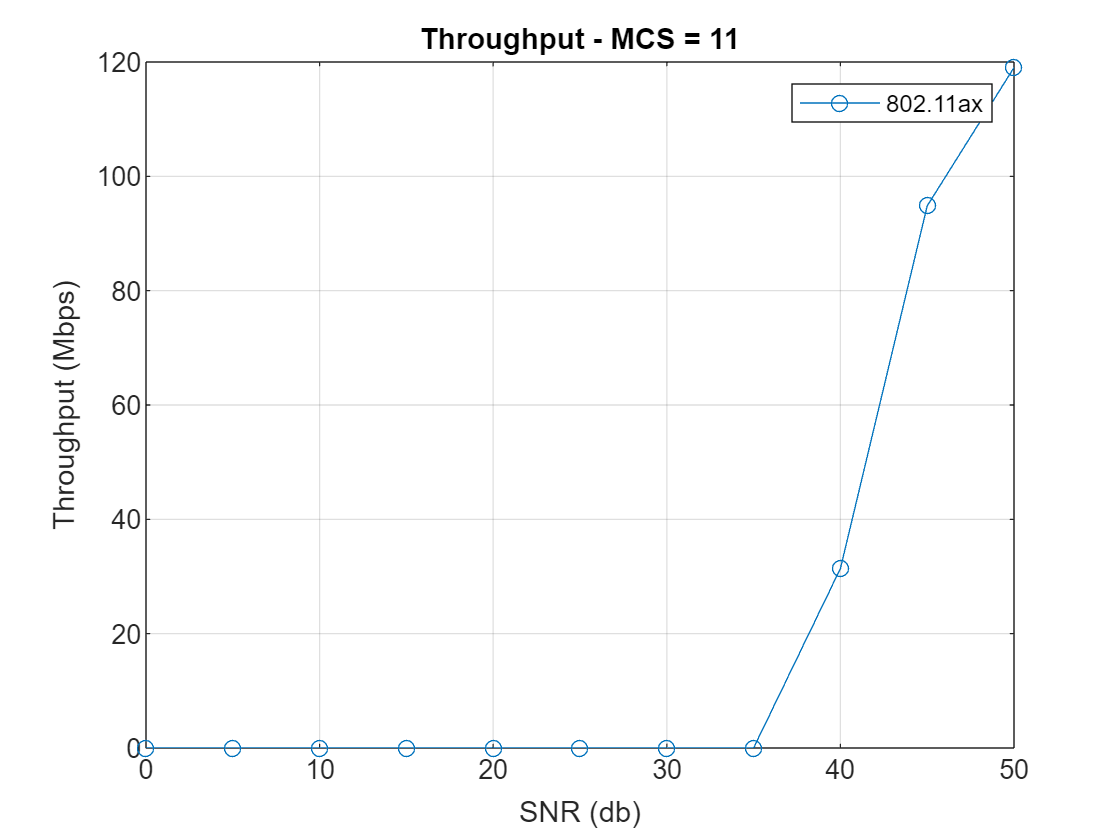

%simulate 802.11ax 1024QAM which is not supported by 802.11ac
cfgHE = su_setup("HE", 'CBW20', 'Direct', 2, 2, 2000, 0.8, 11);
TGAXchannel = channel_setup("TGAX", 'CBW20', wlanSampleRate(cfgHE), 'Model-C', 2, 2, 0.089);
throughput = AX_SUsimulation(cfgHE, TGAXchannel, snr, Nsimulation, 0);
figure;
plot(snr, throughput, '-o');
xlabel('SNR (db)');
ylabel('Throughput (Mbps)');
title('Throughput - MCS = 11');
legend("802.11ax");
grid on;

## Part4: Doppler Effect

In this section, we are going to investigate how mobility impacts the throughput performance of 802.11ax and 802.11ac. As speed increases, the Doppler effect introduces challenges such as frequency shifts and channel fluctuations.

**Observations: **

Doppler effect leads to performance degradation for both 802.11ax and 802.11ac. When the speed reaches 20m/s, the performance of 802.11ax becomes 88.5% of its peak throughput and the performance of 802.11ac becomes 80% of its peak throughput, which shows 802.11ax is more resilient to doppler effect compared to 802.11ac.

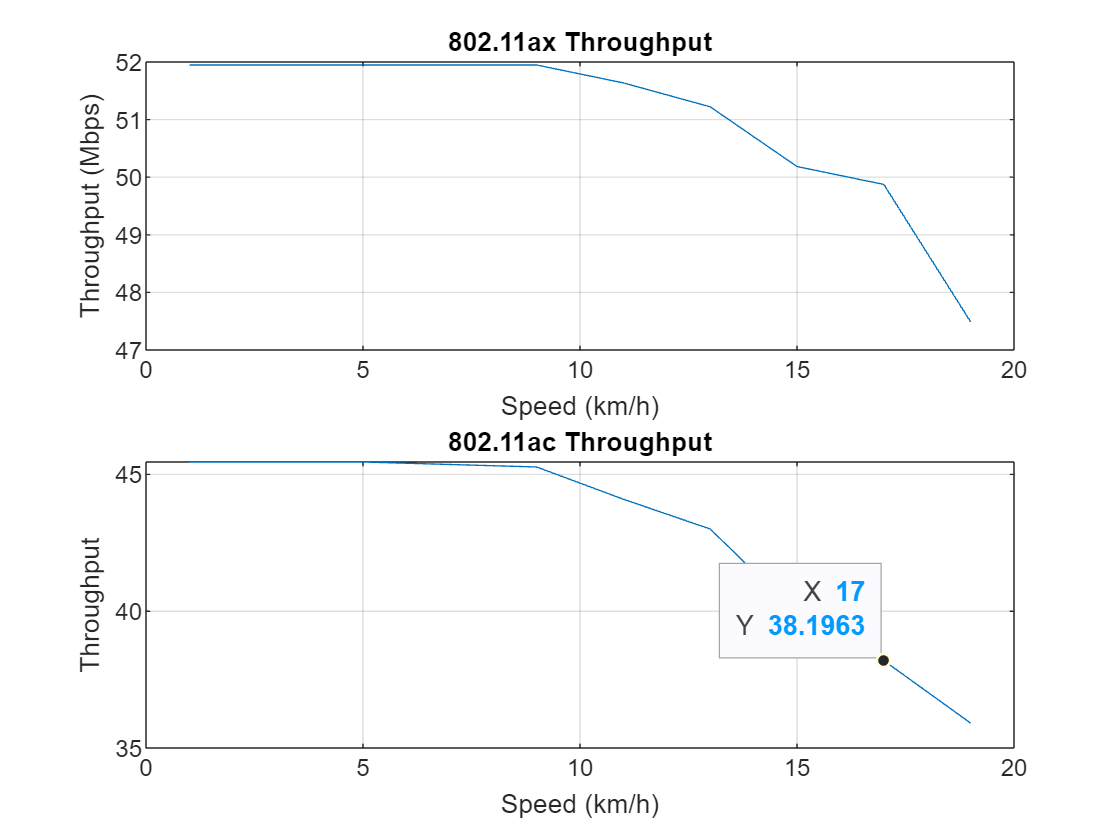

Nsimulation = 500;
speed = 1:2:20;  %7.2km/h = 2 m/s
snr_temp = 45;
Nspeed = numel(speed);

throughputResults_AX = zeros(Nspeed, 1);
throughputResults_AC = zeros(Nspeed, 1);

%setup high-efficiency single user waveform
cfgHE = su_setup("HE", 'CBW20', 'Direct', 2, 2, 2000, 0.8, 3);

%setup VHT 
cfgVHT = su_setup("VHT", 'CBW20', 'Direct', 2, 2, 2000, 'Long', 3);

%simulating with different speed
for i = 1 : Nspeed
    TGAXchannel = channel_setup("TGAX", 'CBW20', wlanSampleRate(cfgHE), 'Model-C', 2, 2, speed(i));
    TGACchannel = channel_setup("TGAC", 'CBW20', wlanSampleRate(cfgVHT), 'Model-C', 2, 2, speed(i));
    throughputResults_AX(i) = AX_SUsimulation(cfgHE, TGAXchannel, snr_temp, Nsimulation, 0);
    throughputResults_AC(i) = AC_SUsimulation(cfgVHT, TGACchannel, snr_temp, Nsimulation, 0);
end

figure()
subplot(2, 1, 1)
plot(speed, throughputResults_AX);
xlabel('Speed (km/h)');
ylabel('Throughput (Mbps)');
title('802.11ax Throughput')
grid on;
subplot(2, 1, 2)
plot(speed, throughputResults_AC);
xlabel('Speed (km/h)');
ylabel('Throughput');
title('802.11ac Throughput')
grid on;

## Part5: The Effect of Pathloss

In this section, we are going to investigate how pathloss impacts the throughput performance of 802.11ax and 802.11ac.

**Observations: **

When pathloss reaches 40db, both 802.11ax and 802.11ac have 0 throughput and 802.11ac shows lower throughput degradation percentage under medium path (10db ~ 30db).

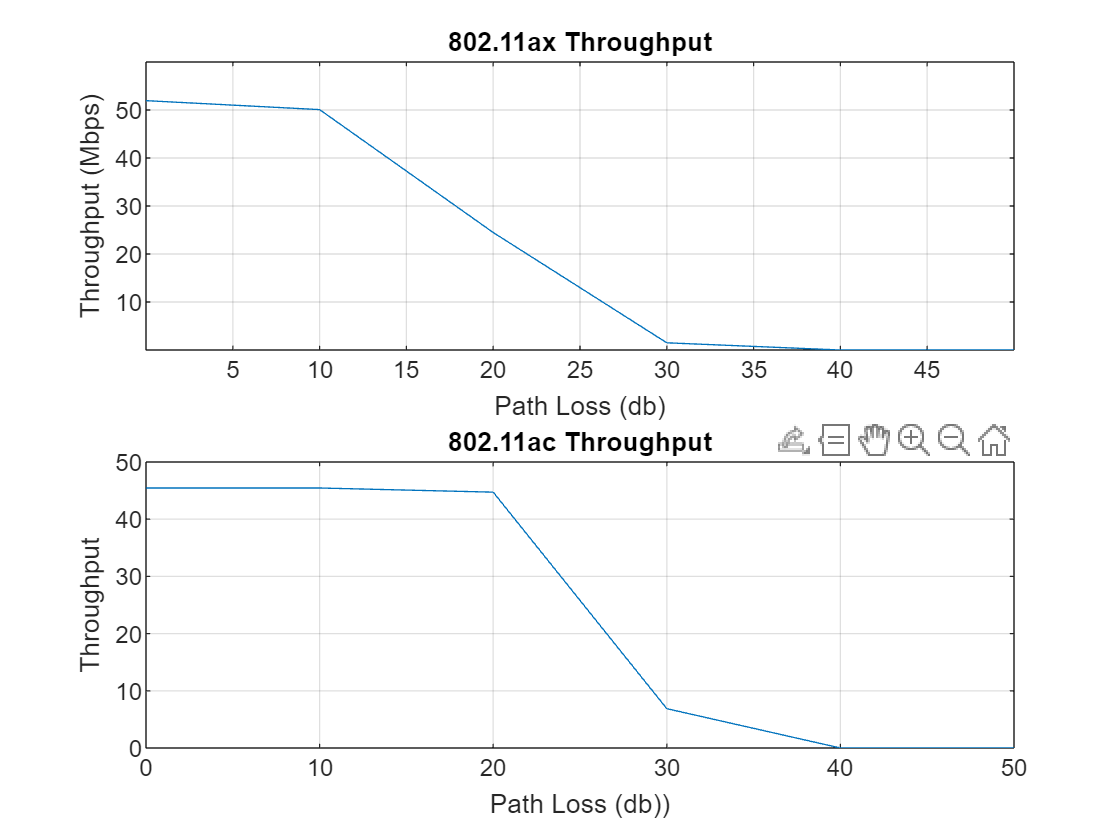

pl_db = 0:10:50;  %0 ~ 50 db
%fixed snr for this test
snr_temp = 45;
Npl = numel(pl_db);


throughputResults_AX = zeros(Npl, 1);
throughputResults_AC = zeros(Npl, 1);

%setup high-efficiency single user waveform
cfgHE = su_setup("HE", 'CBW20', 'Direct', 2, 2, 2000, 0.8, 3);

%setup VHT 
cfgVHT = su_setup("VHT", 'CBW20', 'Direct', 2, 2, 2000, 'Long', 3);

TGAXchannel = channel_setup("TGAX", 'CBW20', wlanSampleRate(cfgHE), 'Model-C', 2, 2, 0.089);
TGACchannel = channel_setup("TGAC", 'CBW20', wlanSampleRate(cfgVHT), 'Model-C', 2, 2, 0.089);

%simulating different pathloss
for i = 1 : Npl
    throughputResults_AX(i) = AX_SUsimulation(cfgHE, TGAXchannel, snr_temp, Nsimulation, pl_db(i));
    throughputResults_AC(i) = AC_SUsimulation(cfgVHT, TGACchannel, snr_temp, Nsimulation, pl_db(i));
end

figure()
subplot(2, 1, 1)
plot(pl_db, throughputResults_AX);
xlabel('Path Loss (db)');
ylabel('Throughput (Mbps)');
title('802.11ax Throughput')
grid on;
subplot(2, 1, 2)
plot(pl_db, throughputResults_AC);
xlabel('Path Loss (db))');
ylabel('Throughput');
title('802.11ac Throughput')
grid on;

## Part6: The Effect of Bandwidth 

In this section, we are going to investigate how  bandwidth impacts the throughput performance of 802.11ax and 802.11ac.

**Observations: **

For CBW20 and CBW40, the trends of throughput are similar comparing to part1, but for CBW80 and CBW160, the throughput of 802.11ac not only increases faster as SNR grows but also reaches higher throughput comparing to 802.11ax.

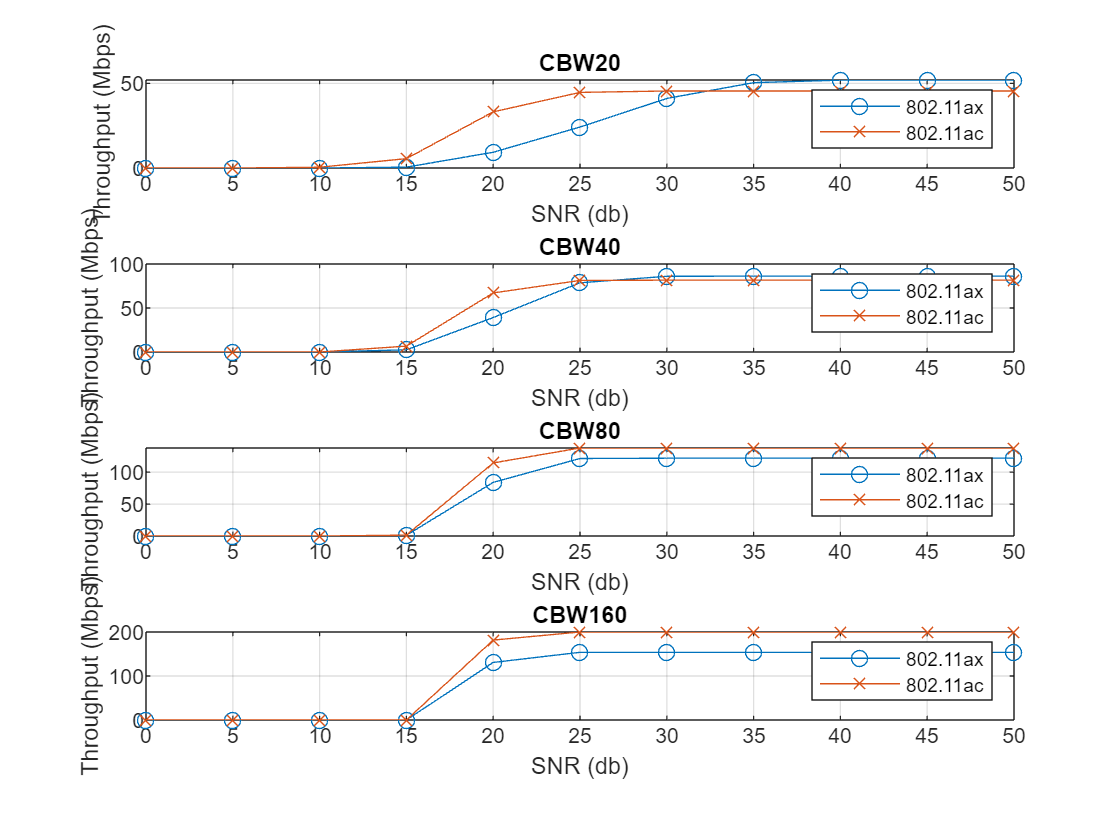


bands = {'CBW20', 'CBW40', 'CBW80', 'CBW160'};
Nbands = numel(bands);

throughputResults_AX = zeros(Nbands, Nsnr);
throughputResults_AC = zeros(Nbands, Nsnr);

%simulating all the bandwidth
for i = 1 : Nbands
    %setup high-efficiency single user waveform
    cfgHE = su_setup("HE", bands{i}, 'Direct', 2, 2, 2000, 0.8, 3);
    %setup VHT 
    cfgVHT = su_setup("VHT", bands{i}, 'Direct', 2, 2, 2000, 'Long', 3);

    TGAXchannel = channel_setup("TGAX", bands{i}, wlanSampleRate(cfgHE), 'Model-C', 2, 2, 0);
    TGACchannel = channel_setup("TGAC", bands{i}, wlanSampleRate(cfgVHT), 'Model-C', 2, 2, 0);

    throughputResults_AX(i, :) = AX_SUsimulation(cfgHE, TGAXchannel, snr, Nsimulation, 0);

    throughputResults_AC(i, :) = AC_SUsimulation(cfgVHT, TGACchannel, snr, Nsimulation, 0);

end


figure;
for i = 1:Nbands
    subplot(Nbands, 1, i)
    plot(snr, throughputResults_AX(i,:), '-o', snr, throughputResults_AC(i,:), '-x');
    xlabel('SNR (db)');
    ylabel('Throughput (Mbps)');
    title([bands(i)]);
    legend('802.11ax', '802.11ac');
    grid on;
end

## Conclusion

Based on the simulation results shown above, we can conclude that  802.11ac often achieves higher throughput at moderate SNR levels and with higher bandwidths. While 802.11ax demonstrates better performance at high SNR levels and mid to low bandwidths. Notably, 802.11ax maintains more stable throughput under doppler effects and it also benefits from high modulation schemes such as 1024-QAM, which are not supported by 802.11ac. Therefore, neither 802.11ax nor 802.11ac can be considered as absolutely better or worse under single-user format and we can choose them depends on the specific scenarios and conditions.